Jiles-Artherton current transfromer model


$$B = \mu_0(H+M)$$



$$M_{an} = M_sf(H_e)$$



$$H_e = H+\alpha M$$



$$M = M_{irr}+M_{rev}$$



$$\frac{dM}{dH}=\frac{c\frac{dM_{an}}{dH_e}+\frac{M_{an}-M}{\frac{\delta k}{\mu_0}-\frac{\alpha(M_{an}-M)}{1-c}}}{1-\alpha c\frac{dM_{an}}{dM_e}}$$


Current transformer model


$$\Delta H = \frac{N_p}{l}\Delta I_p - \frac{N_s}{l}\Delta I_s $$


$N_p$,$N_s$ – the number of turns in the primary and secondary;

$I_p$,$I_s$ – the current in the primary and secondary;

$l$ – length of the flux path;


$$\frac{N_s Q}{\Delta t}\Delta B = R_s\left( I^{old}_s+\frac{\Delta I_s}{2} \right) + \frac{L_s}{\Delta t}\Delta I_s$$


$Q
$ – the cross section of the core of the CT;

$\Delta B$ –  the change in flux density in the core;

$R_s$ – the sum of secondary winding and burden resistance;

$L_s$ – the sum of secondary winding and burden inductance;

$I^{old}_s$ – secondary current during the previous stime step;


$$\Delta B = \mu_0(\Delta H + \Delta M)$$


Jiles-Artherton equaitons


$$M_{an} (H_e)= M_s \frac{a_1H_e+H_e^b}{a_3+a_2H_e+H_e^b}$$


and the derrivative


$$\frac{dM_{an}}{dH_e}(H_e)=M_e\frac{a_1a_3+ba_3H_e^{(b-1)}+(b-1)(a_2-a_1)H_e^b}{(a_3+a_2H_e+H_e^b)^2}$$



$$k_{modified} = k \left [ 1-\beta\left ( \frac{M}{M_s} \right) \right]$$


Parametrs of the CT model with Langevin function

% Interdomain coupling
alpha = 3e-5; %1.32e-5;
% Sat. Anhyst. Magnetization
Ms = 1.7e6; %1.72e+6;
%Domainf pinning paramter
k = 4e-5; %5e-5;
% Domaing Flexing Parameter
c = 0.08; %0.1;
% Adjusting K with M
beta = 0.96;

a1 = 2550; %2730
a2 = 3150; %3209
a3 = 15000; %20294
b = 2; %2

Curve calculation

[H, M, B] = GetSatCurve(alpha, Ms, k, c, beta, a1, a2, a3, b);

RTDS $H(B)
$ equation 

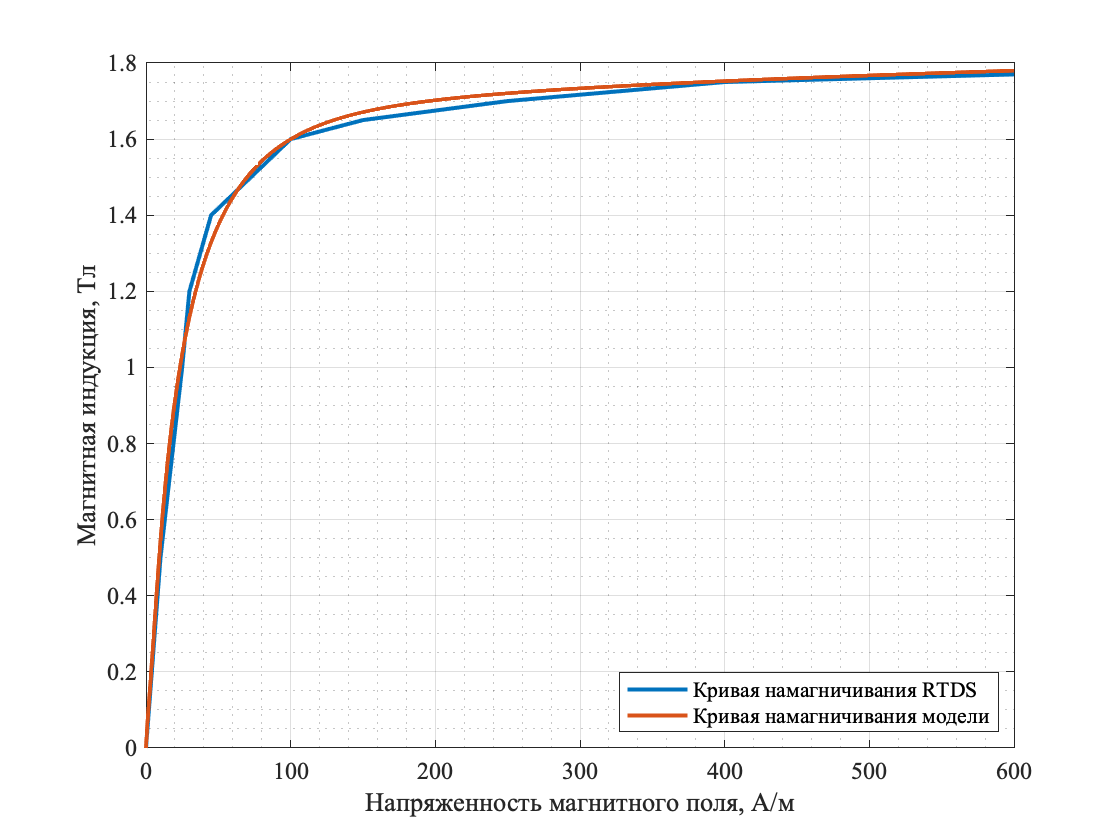

HB = [0	0
    10	0.5
    25	1
    30	1.2
    45	1.4
    100	1.6
    150	1.65
    250	1.7
    400	1.75
    500	1.76
    600	1.77
    ];
plot(HB(:,1),HB(:,2),'LineWidth',2);
hold on;
plot(H,B, 'LineWidth',2);
legend({'Кривая намагничивания RTDS','Кривая намагничивания модели'}, "Location","southeast")
hold off;
grid on;
grid minor;
xlim([0,600]);
ax = gca;
ax.FontName = 'Times';
ax.FontSize = 12;
ax.XLabel.String = 'Напряженность магнитного поля, А/м';
ax.YLabel.String = 'Магнитная индукция, Тл';

% exportgraphics(gcf,'HB.pdf','ContentType','vector')

% Interdomain coupling
params.alpha = 3e-5; 
% Sat. Anhyst. Magnetization
params.Ms = 1.7e6; 
%Domainf pinning paramter
params.k = 4e-5; 
% Domaing Flexing Parameter
params.c = 0.08; 
% Adjusting K with M
params.beta = 0.96;


params.a1 = 2550; 
params.a2 = 3150; 
params.a3 = 15000;
params.b = 2;

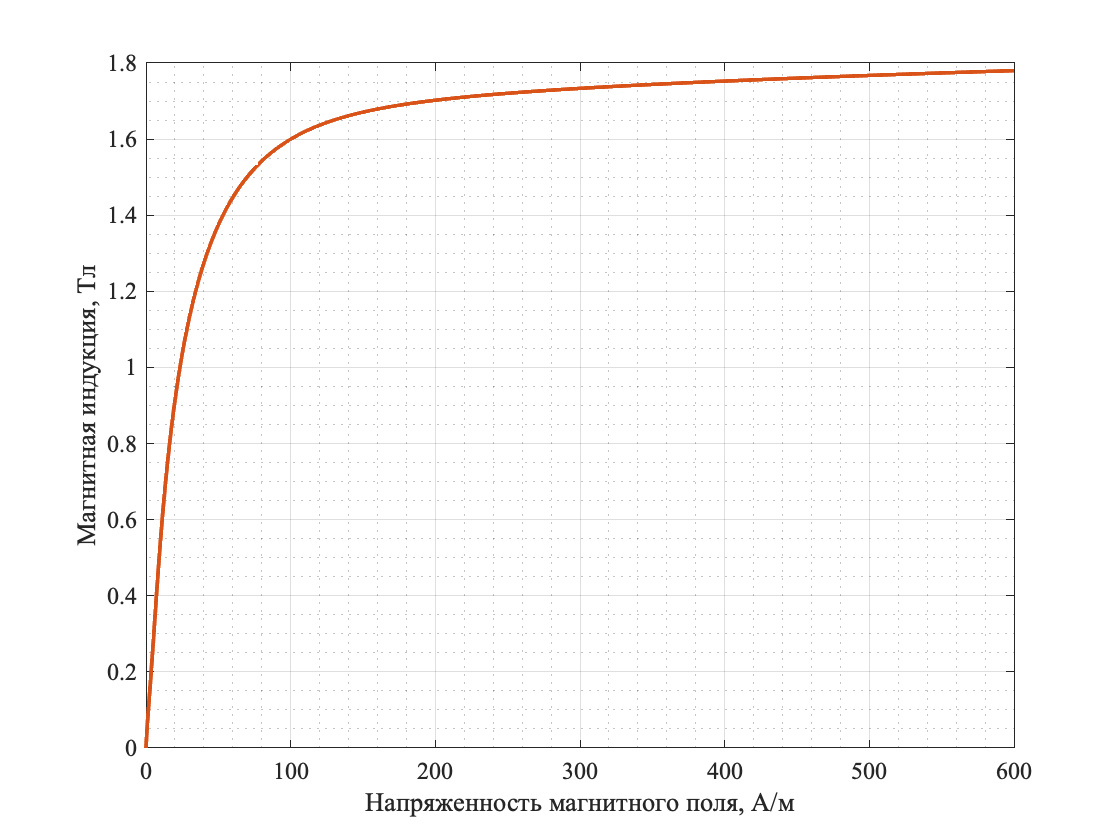

[Hp, Mp, Bp] = GetSatCurve(params);
plotHB([Hp',Bp'], [H',B']);

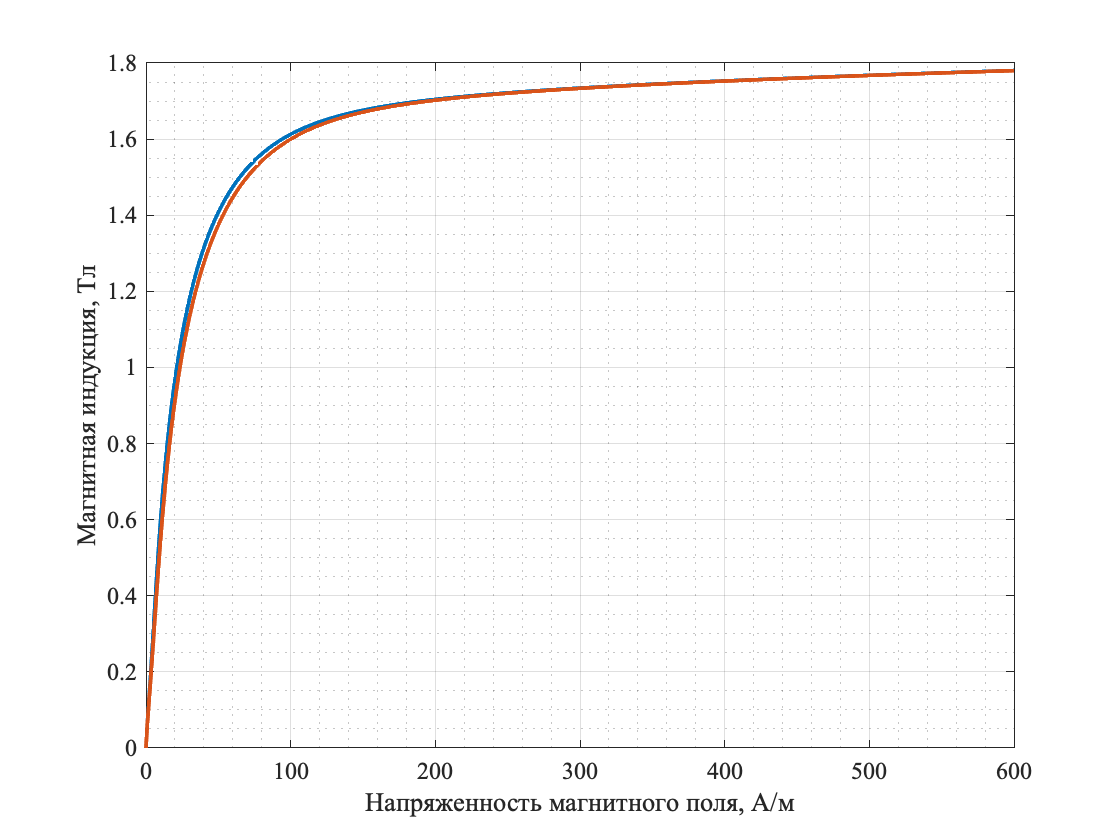

clear alpha Ms k c mu0 delta a1 a2 a3 b He M_an dM_an MMan dM i;

clear H B M HB;